srcDir = "..\srcImages\";
building_dark = readraw(srcDir + "building.raw");

    "→Retrieving Image "    "..\srcImages\building.raw"    " ..."



building_noise = readraw(srcDir + "building_noise.raw");

    "→Retrieving Image "    "..\srcImages\building_noise.raw"    " ..."



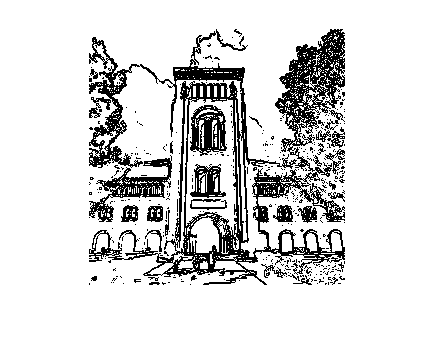


edgeMap = sobelEdgeMap(building_dark, @sobel3x3Horizontal, @sobel3x3Vertical, 0.15);
imshow(edgeMap);

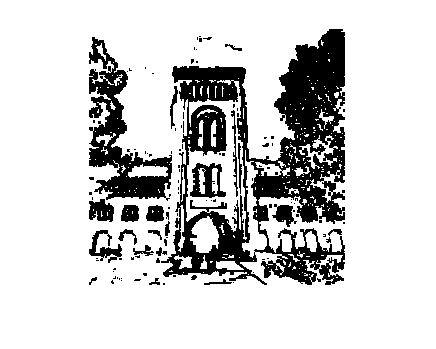


edgeMap = laplaceEdgeMap(building_dark, 0.2);
imshow(edgeMap);

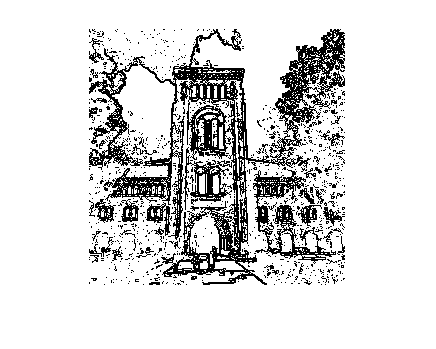


edgeMap = sobelEdgeMap(building_noise, @sobel3x3Horizontal, @sobel3x3Vertical, 0.2);
imshow(edgeMap);

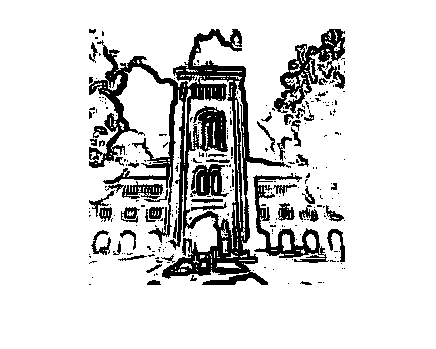


edgeMap = sobelEdgeMap(building_noise, @sobel7x7Horizontal, @sobel7x7Vertical, 0.2);
imshow(edgeMap);

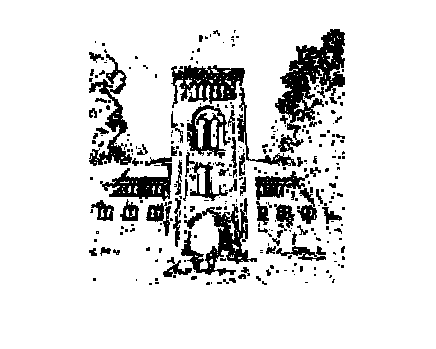


edgeMap = laplaceEdgeMap(building_noise, 0.5);
imshow(edgeMap);

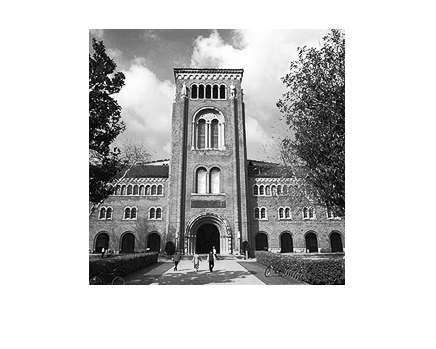


building_contrast = contrastHistogramEqualized(building_dark);
imshow(building_contrast);

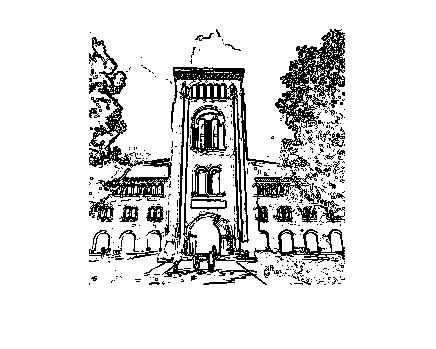


edgeMap = sobelEdgeMap(building_contrast, @sobel3x3Horizontal, @sobel3x3Vertical, 0.2);
imshow(edgeMap);

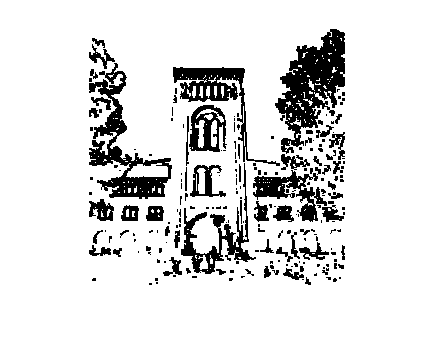


edgeMap = laplaceEdgeMap(building_contrast, 0.2);
imshow(edgeMap);

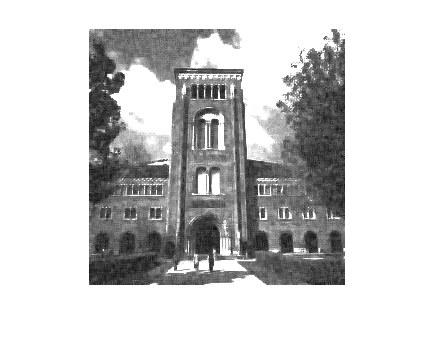


building_blur = applyMedianFilter(building_noise, 5);
imshow(building_blur);

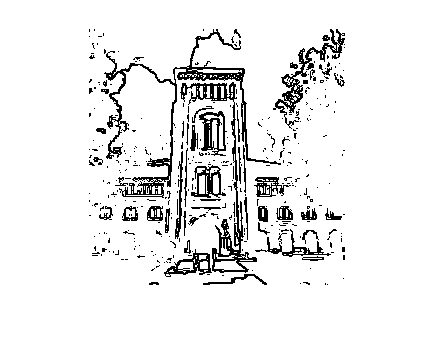


edgeMap = sobelEdgeMap(building_blur, @sobel3x3Horizontal, @sobel3x3Vertical, 0.2);
imshow(edgeMap);

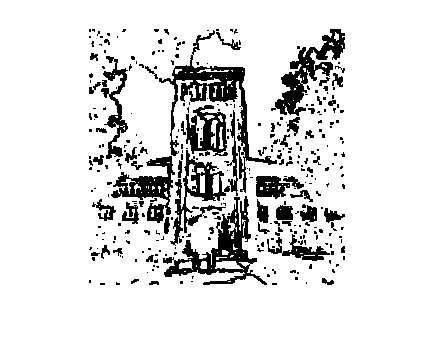


edgeMap = laplaceEdgeMap(building_blur, 0.2);
imshow(edgeMap);